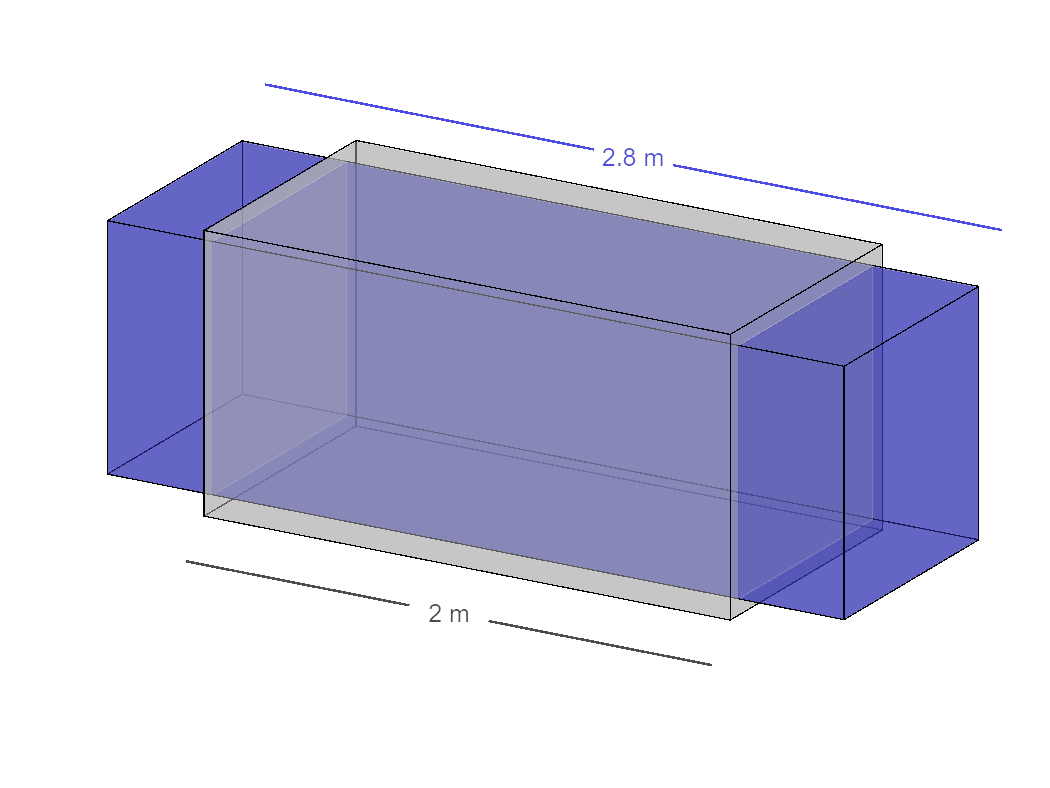

close all

nu = 0.28; % Poisson's ratio
longStretch = 1.4;
L0 = 2;   % Initial length (m)
w0 = 1;   % Initial width (m)

visualizeAxialStrain(longStretch, L0, nu, w0);

function visualizeAxialStrain(longStretch, L0, nu, w0)
    
    % Calculations
    % 6666666666 check these calculations
    L = longStretch*L0;
    deltaL = longStretch*L0-L0;
    epsL = (L-L0)/L0; % Longitudinal strain
    epsT = - nu*epsL; % Transverse strain
    transverseStretch = epsT + 1 - 1e-3;
    % end 666
    
    % Visualization parameters
    cubeEdgeAlpha = 1;
    cubeAlpha = 0.5;
    cubeColors = [1 1 1]*0.7;
    cubeColorsDeformed = [50 50 180]/255;
    cubeAlphaDeformed = 0.5;
    axLims = [-1 1 -2 2 -1 1]*0.6;
    
    % Cube and deformations
    [vertices,faces,normals] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*w0;
    verticesDeformed = vertices;
    verticesDeformed(:,2) = verticesDeformed(:,2)*longStretch;
    verticesDeformed(:,[1,3]) = verticesDeformed(:,[1,3])*transverseStretch;
    
    % Create plot
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColors,"FaceAlpha",cubeAlpha);
    hold on
    patch("Vertices",verticesDeformed,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColorsDeformed,"FaceAlpha",cubeAlphaDeformed);

    % Label for L0
    xyz1 = vertices(2,:)';
    xyz2 = vertices(3,:)';
    offsetVector = [1; 0; -1]*0.12;
    labelText = num2str(L0,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.3]);

    % Label for L
    xyz1 = verticesDeformed(5,:)';
    xyz2 = verticesDeformed(8,:)';
    offsetVector = -[1; 0; -1]*0.15;
    labelText = num2str(L,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.9]);

    hold off
    view(120,20)
    axis equal
    axis(axLims)
    set(gca,"Clipping","off")
    axis off
end

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function dimensionLabel(xyz1,xyz2,offsetVector,labelText,color)
    mag = norm(xyz1-xyz2);
    xyzm = (xyz1 + xyz2)/2;
    xyzm1 = (xyz1*(0.5+0.15/mag) + xyz2*(0.5-0.15/mag));
    xyzm2 = (xyz1*(0.5-0.15/mag) + xyz2*(0.5+0.15/mag));
    plot3([xyz1(1),xyzm1(1),NaN,xyzm2(1),xyz2(1)]+offsetVector(1),...
          [xyz1(2),xyzm1(2),NaN,xyzm2(2),xyz2(2)]+offsetVector(2),...
          [xyz1(3),xyzm1(3),NaN,xyzm2(3),xyz2(3)]+offsetVector(3),...
          "-","Color",color,"LineWidth",1)

    xyzt = xyzm + offsetVector;

    text(xyzt(1),xyzt(2),xyzt(3),labelText,"Color",color,...
        "VerticalAlignment","middle","HorizontalAlignment","center");

end